# Textra-02. Analysing the resolution-leakage trade-off in finite time series PSD estimation

## Introduction

In this tutorial an analysis of the DTFT of different windows is performed. The aim is to illustrate how the use of a window in the time domain allows different trade-offs between resolution and leakage in spectral estimation from data.

When estimating the spectrum from a finite time series (with the direct approach through the DTFT of the data, but also with the indirect approach through the DTFT of the autocovariance function), the underlying assumption is that the data are obtained through a *windowing *operation in time domain. The windowing operation is the product of an infinite time series with a window that takes non-zero values only in a time range (the time range for which the finite time series is available). This operation has an impact in the frequency domain: the DTFT of the finite time series results from a convolution of the (unknown) true spectrum of the infinite time series with the DTFT of the employed window. The DTFT of a window typically shows a main-lobe and side-lobes. The width of the main-lobe represents a loss in resolution, and the level of side-lobes represents *leakage* in the frequency domain, since frequency content goes from the original frequency in the true spectrum to neighbour frequencies. 

As a conclusion, when estimating a spectrum from a finite time series, deviations with respect to the true spectrum arise due to the two mentioned phenomena, loss of resolution and leakage. The DTFT of the different windows illustrate different possible trade-offs between them.

The tutorial compares the DTFT of two windows.

## Tutorial

First of all, add mVARbox to path, and set the tutorial parameters.

setmVARboxPath

mVARbox path has been added to MATLAB path



clear
clc
close all


%%% Parameters

window_1_name = 'rectangular';  % Windows considered in the comparison
window_2_name = 'Hann';         % For a list of window names, see function 
                                % 'initialise_window'. 

N_window    = 40;               % Number of window elements.
                                % It Must be even because this tutorial 
                                % considers data_window.

delta_t     = 1;                % sampling time [seconds]
f_max       = 1/(2*delta_t);    % maximum frequency
N_f         = 1000;             % number of elements of the frequency vector


%%% Plot parameters
font_size       = 14;
figure_position = [0 0 1000 400];
CC              = colororder;
color_1         = CC(1,:);
color_2         = CC(2,:);

Initialise and get two window objects using function `get_window`.

window_type = 'data_window';

window_1 = initialise_window('type',window_type,...
                             'N',N_window,...
                             'name',window_1_name);

window_1 = get_window(window_1);

window_2 = initialise_window('type',window_type,...
                             'N',N_window,...
                             'name',window_2_name);

window_2 = get_window(window_2);

Create a data object from each window, with the fields required by function `get_DTFT_data`.

ind_var = 't';

data_1 = initialise_data('ind_var',ind_var,...
                         'delta_x',delta_t,...
                         'y_values',window_1.y_values);

data_2 = initialise_data('ind_var',ind_var,...
                         'delta_x',delta_t,...
                         'y_values',window_2.y_values);

Define the frequency vector to evaluate the DTFT, and get the DTFT of the windows. 

f_vector = transpose(linspace(-f_max,f_max,N_f));

DTFT0 = initialise_DTFT('x_values',f_vector);

[DTFT_1] = get_DTFT_data(data_1, DTFT0);

[DTFT_2] = get_DTFT_data(data_2, DTFT0);

Plot the two windows in the time domain.

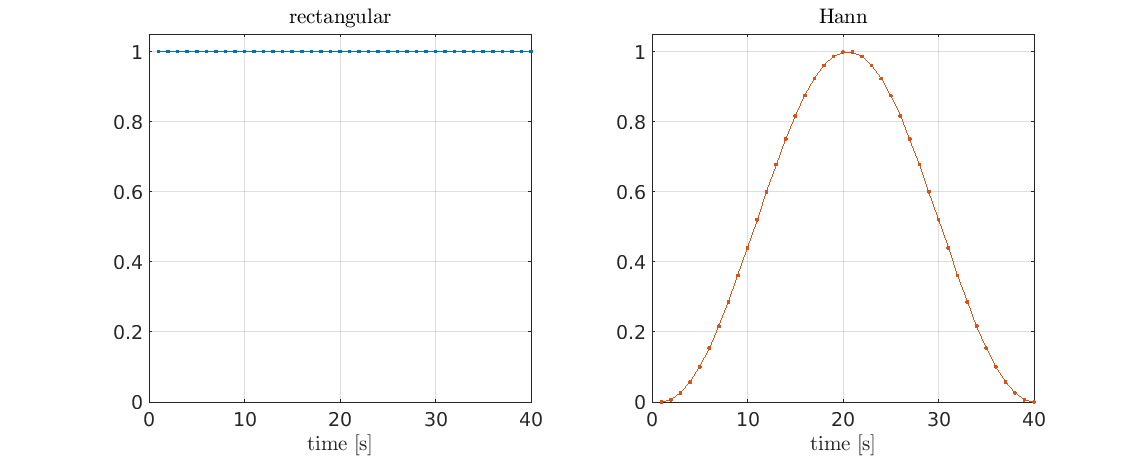

figure

subplot(1,2,1)
x = data_1.x_values;
y = data_1.y_values;
plot(x,y,'.-','color',color_1)
xlabel('time [s]','Interpreter','latex')
ylim([0 1.05])
grid on
title(window_1_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

subplot(1,2,2)
x = data_2.x_values;
y = data_2.y_values;
plot(x,y,'.-','color',color_2)
xlabel('time [s]','Interpreter','latex')
ylim([0 1.05])
grid on
title(window_2_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

Plot the DTFT of the windows. Since the DTFT is complex-valued, the plots represent the magnitude of the DTFT.

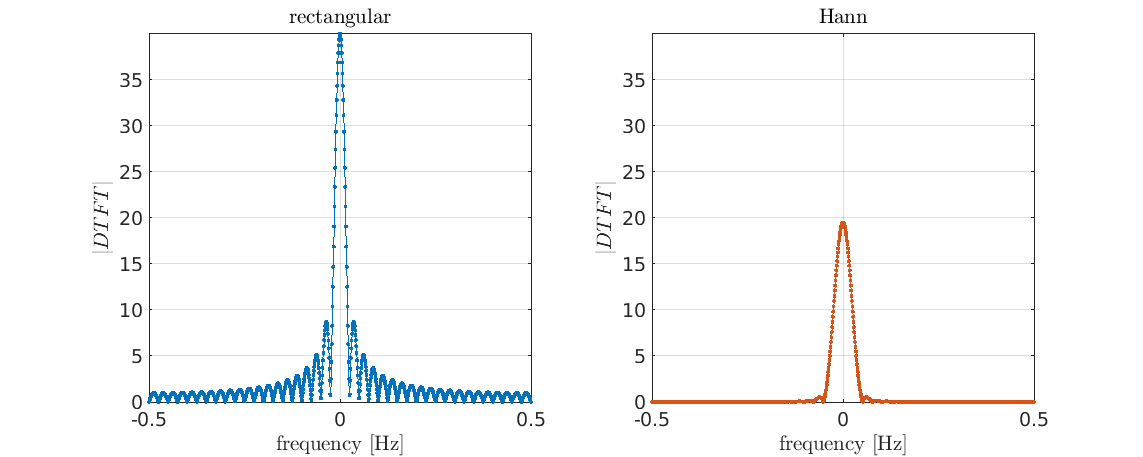

% maximum values to set y-axis
y_max_1 = max(abs(DTFT_1.y_values));
y_max_2 = max(abs(DTFT_2.y_values));
y_max = max(y_max_1,y_max_2);


% plots

figure

subplot(1,2,1)
x = DTFT_1.x_values;
y = abs(DTFT_1.y_values);
plot(x,y,'.-','color',color_1)
xlabel('frequency [Hz]','Interpreter','latex')
ylabel('$\left| DTFT \right|$','Interpreter','latex')
ylim([0 y_max])
grid on
title(window_1_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

subplot(1,2,2)
x = DTFT_2.x_values;
y = abs(DTFT_2.y_values);
plot(x,y,'.-','color',color_2)
xlabel('frequency [Hz]','Interpreter','latex')
ylabel('$\left| DTFT \right|$','Interpreter','latex')
ylim([0 y_max])
grid on
title(window_2_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

The interpretation of the previous plot is as follows: given a sinusoid signal with frequency $f_0$, the estimated PSD from a finite time series of the sinusoid is the convolution of the true spectrum (delta de dirac at frequency $f_0$) with the spectrum of the employed window (rectangular, unless a specific window is applied to the time series). Thus, the resulting estimated PSD is a scaled version of the previous figure centred at frequency $f_0$, which represents just an approximation of the true spectrum (delta de dirac).

Usually, the previous figure is represented in terms of decibels, dB, defined as $10 \cdot \text{log}_{10} \frac{y(f)}{y_{max}}$.

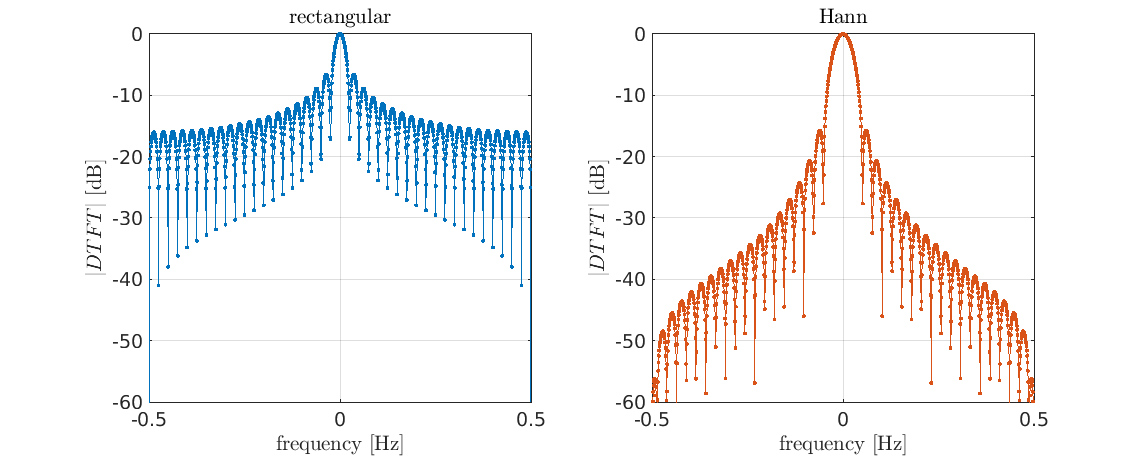

% maximum values to compute decibels
y_max_1 = max(abs(DTFT_1.y_values));
y_max_2 = max(abs(DTFT_2.y_values));


% plots

figure

subplot(1,2,1)
x = DTFT_1.x_values;
y = abs(DTFT_1.y_values);
plot(x,10*log10(y/y_max_1),'.-','color',color_1)
xlabel('frequency [Hz]','Interpreter','latex')
ylabel('$\left| DTFT \right|$ [dB]','Interpreter','latex')
grid on
xlim([-f_max,f_max])
ylim([-60 0])
title(window_1_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

subplot(1,2,2)
x = DTFT_2.x_values;
y = abs(DTFT_2.y_values);
plot(x,10*log10(y/y_max_2),'.-','color',color_2);
xlabel('frequency [Hz]','Interpreter','latex')
ylabel('$\left| DTFT \right|$ [dB]','Interpreter','latex')
grid on
xlim([-f_max,f_max])
ylim([-60 0])
title(window_2_name,'Interpreter','latex')
set(gca,'fontsize',font_size)

set(gcf,'position',figure_position)

## Remarks

- You can visualize the different main-lobe widths and side-lobes levels of the different windows by changing the variables `window_1_name` and `window_2_name`. The rectangular window has the narrowest main-lobe, thus the best resolution, but the highest side-lobe levels, thus the highest leakage.

- The resolution of the PSD is given by the width of the main-lobe (in terms of frequency range covered by this lobe). For a given window, the resolution depends strictly on the time span of the time series, i.e., the product $N_{window} \cdot \Delta t$. The higher the time span, the smaller the main-lobe width (thus the higher the resolution). By considering half of `N_window `and twice `delta_t`, the obtained main-lobe seems to double its width in the plot, but note that the maximum frequency $f_{max}$ is also reduced by half. Thus, the main-lobe width is actually the same, as expected because the time span of the window given by the product $N_{window} \cdot \Delta t$ has not changed. Conversely, if `N_window` increases and `delta_t` remains constant, the width of the main-lobe decreases (higher resolution), because the time span of the window is higher.

- Note that the maximum value of the main-lobe increases with parameters `N_window` and `delta_t`, because the duration of the window ($N_{window} \cdot \Delta t$), and thus the energy of the window, increases as well. For this reason, PSD estimation methods that involve windows need to re-scale the obtained spectrum according to the window energy to remove this effect.

- The last figure shows the DTFT in terms of $\left| DTFT \right|$. However, some books illustrate $\left| DTFT \right|^2$. This is so because the spectrum is related to the square DTFT. Be aware of this when comparing the plots obtained in this tutorial with similar results from literature, because the side-lobes level vary between the two representations (even though the comparison between windows is qualitatively the same).